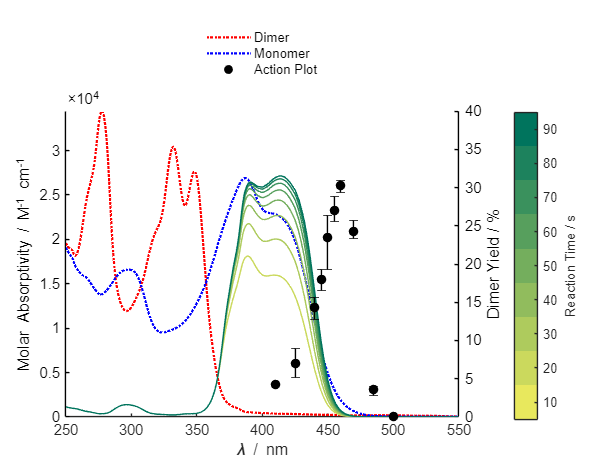

clear
phi1 = 0.01; %QY mono -> dimer
phi2 = 0.9; %QY dimer -> mono
I = 1.22e16; %photon flux
NA = 6.022e23; %Avagadro's Number
SmoothFactor = 10; %Smooth data stepsize (increments of spectrometer resolution)
concentrationUVVis = 20e-6; %Molar concentration of molecules in UV-Vis
concentrationExperiment = 1e-3; %Molar concentration of molecules used in experiment
volume = 500e-6; %Volume of sample
iTime = 10; %initial time
fTime = 90; %final time
timeStep = 9; %timestep (number of model graphs)

%import data
MonoAbsFile = 'PyChalTransMonomerACN.csv';
DimerAbsFile = 'PyChalDimerACN.csv';
MonoAbs = readmatrix(MonoAbsFile);
DimerAbs = readmatrix(DimerAbsFile);
APFile = 'APDimer.csv';
AP = readmatrix(APFile); %AP = Action Plot

%smoothing and convert from Absorbance to Molar Absorptivity based on concentration
MolarAbsM = movmean(MonoAbs(:,2),SmoothFactor)/concentrationUVVis;
MolarAbsD = movmean(DimerAbs(:,2),SmoothFactor)/concentrationUVVis;

Lambda = linspace(250, 600, length(MolarAbsM)); % Wavelength Data

t = linspace(iTime, fTime, timeStep); %time vector
cmap = flip(summer(length(t))/1.1); %colourmap
N0 = concentrationExperiment*NA*volume; %initial molecules #
kMD = phi1 * ((MolarAbsM*log(10)*10^3)/ NA) * I; %rate coefficient for km->d
kDM = phi2 * ((MolarAbsD*log(10)*10^3)/ NA) * I; %rate coefficient for kd->m
kMM = (1-10.^-(MonoAbs(:,2))); %scaling for km->m*, set this to 1 to exclude this factor, then change kMM(i) to kMM in below loop

%loop though each time for model
for j = 1:length(t)
    for i = 1:length(MolarAbsM)
        NdLam(i) = rates2plus2(N0, kMD(i), kDM(i), kMM(i), t(j)); %set kMM(i) to kMM if don't want to include kMM
    end
    timeNdLam{j} = NdLam; % add each to cell
end

%plot all data
figure
    hold on
    yyaxis left
    plot(Lambda,MolarAbsD, linestyle=":", linewidth=1.5, color='r')
    plot(Lambda,MolarAbsM, linestyle=":", linewidth=1.5, color='b')
    ylabel("Molar Absorptivity / M^{-1} cm^{-1}")
    ylim([0 inf])
    yyaxis right
for k = 2:length(timeNdLam)    
    plot(Lambda,(timeNdLam{k}/N0)*100, 'Marker', 'none', linestyle="-", linewidth=1, color=cmap(k,:)) %
end
    scatter(AP(:,1),AP(:,2), "filled", MarkerFaceColor='k')
    errorbar(AP(:,1), AP(:,2), AP(:,3), AP(:,4), 'o', 'color', 'k');
    ax = gca;
    ax.YAxis(1).Color = 'k';
    ax.YAxis(2).Color = 'k';
    hold off
    colormap(cmap);
    cb = colorbar;
    cb.Ticks = linspace(0+(1/length(t)/2), 1-(1/length(t)/2), length(t)); %scale tick marks appropriately
    set(cb, 'TickLabels', linspace(t(1), t(end), length(t)));
    cb.Label.String = 'Reaction Time / s';
    xlabel("{\it\bf\lambda} / nm")
    ylabel("Dimer Yield / %")
    xlim([250 550])
    ylim([0 40])
    legend("Dimer", "Monomer", "", "", "", "", "", "", "", "", "Action Plot", "Location","northoutside", 'box', 'off')

%rate model for photocycloaddition (Equation S5)
function Nd = rates2plus2(N0, kMD, kDM, kMM, t)
    k = 4*kMD*kMM + kDM;
    Kall = 2*kMD*kMM/k;
    Nd = N0*Kall*(1-exp(-k.*t));
end
